# [使用虚幻引擎模拟可视化自动泊车代客](https://ww2.mathworks.cn/help/driving/ug/visualize-automated-parking-valet-using-3d-simulation.html)

此示例展示了如何在使用 Epic Games® 的 Unreal Engine® 渲染的 3D 模拟环境中可视化车辆运动。它紧跟[Simulink](https://ww2.mathworks.cn/help/driving/ug/automated-parking-valet-in-simulink.html)示例中的自动泊车代客。

## **介绍**

Automated Driving Toolbox™ 在 Simulink® 中集成了 Unreal Engine 仿真环境。您可以使用此环境在预建场景中可视化车辆的运动。该环境提供了一种直观的方式来分析路径规划和车辆控制算法的性能。[Simulink 中的自动代客泊车](https://ww2.mathworks.cn/help/driving/ug/automated-parking-valet-in-simulink.html)示例展示了如何在 Simulink 中为自动泊车代客系统设计路径规划和车辆控制算法。此示例说明如何扩充模型以使用可视化引擎可视化场景中的车辆运动。此工作流中的步骤是：

- 从 3D 场景创建成本图。

- 根据场景创建路线计划。

- 在 Simulink 中配置 3D 场景和自我车辆。

- 在 3D 场景中模拟和可视化车辆的运动。

获取现在打开的系统列表，以便在此示例中打开的任何系统都可以在最后关闭。

startingOpenSystems = find_system('MatchFilter', @Simulink.match.allVariants);

## **从 3D 场景创建 Costmap**

可视化集成带有许多预建场景。每个场景都带有高分辨率图像，可用于探索场景。使用`helperShowSceneImage`函数显示图像。此示例使用[大型停车场](https://ww2.mathworks.cn/help/driving/ref/largeparkinglot.html)场景。

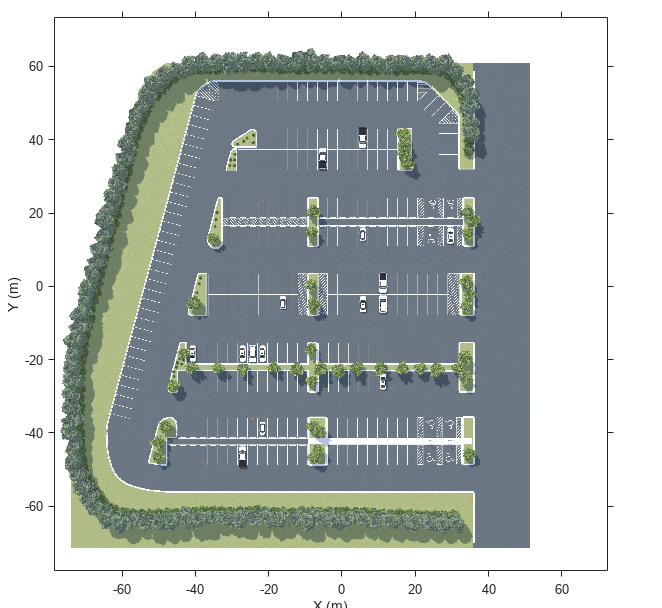

% Load and display the image of the parking lot
sceneName = 'LargeParkingLot';
[sceneImage, sceneRef] = helperGetSceneImage(sceneName);

% Visualize the scene image
figure
% sceneImage 的大小应为 5104x5104x3，但实际大小为 5928x5928x3。
helperShowSceneImage(sceneImage, sceneRef)

如此高分辨率的图像是对某种分辨率下环境的准确描述。您可以使用此图像创建[`vehicleCostmap`](https://ww2.mathworks.cn/help/driving/ref/vehiclecostmap.html)路径规划和导航。

首先，从图像中估计可用空间。自由空间是车辆可以行驶而不会与其他静态物体（例如停放的汽车、锥体和道路边界）发生碰撞并且不会越过标记线的区域。在此示例中，您可以根据图像的颜色估计可用空间。使用Image Processing Toolbox 中的[Color Thresholder](https://ww2.mathworks.cn/help/images/ref/colorthresholder-app.html)应用程序执行分割并从图像生成二值图像。`helperCreateCostmapFromImage`您还可以使用示例末尾的辅助函数 来生成二进制图像：

或者，加载预生成的二进制图像。

sceneImageBinary = imread('sim3d_LargeParkingLotBinary.bmp');

接下来，从二值图像创建成本图。使用二值图像指定每个单元格的成本值。

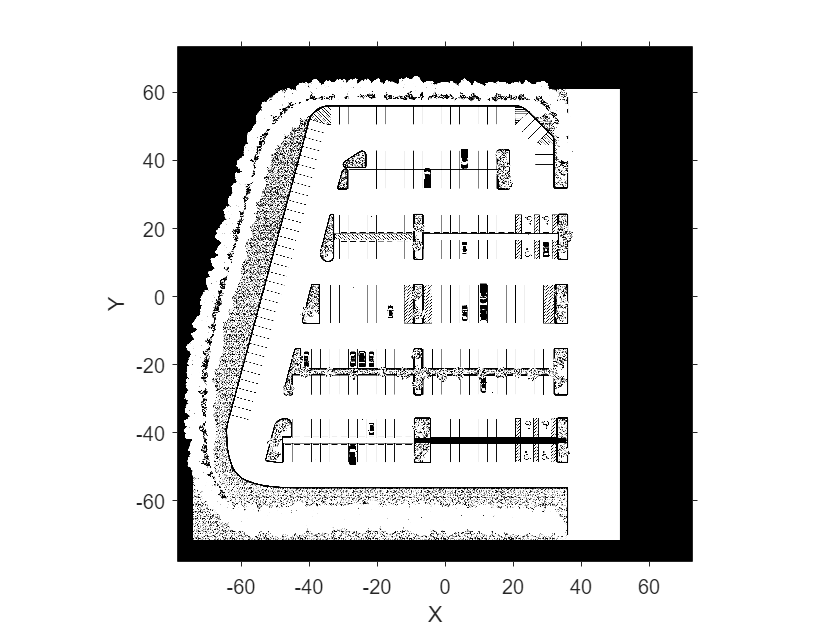

% Get the left-bottom corner location of the map
mapLocation = [sceneRef.XWorldLimits(1), sceneRef.YWorldLimits(1)]; % [meters, meters]

% Compute resolution
mapWidth = sceneRef.XWorldLimits(2)-sceneRef.XWorldLimits(1); % meters
cellSize = mapWidth/size(sceneImageBinary, 2);

% Create the costmap
costmap = vehicleCostmap(im2single(sceneImageBinary), 'CellSize', cellSize, 'MapLocation', mapLocation);

figure
plot(costmap, 'Inflation', 'off');

legend off

您还需要根据 3D 场景中可用的车辆指定将自动停放的车辆的尺寸。[此示例使用两厢车](https://ww2.mathworks.cn/help/driving/ref/hatchback.html)的尺寸。这些维度需要在成本图和 Simulink 模型之间保持一致。

centerToFront = 1.104; % meters
centerToRear  = 1.343; % meters
frontOverhang = 0.828; % meters
rearOverhang  = 0.589; % meters
vehicleWidth  = 1.653; % meters
vehicleHeight = 1.513; % meters
vehicleLength = centerToFront + centerToRear + frontOverhang + rearOverhang;

vehicleDims = vehicleDimensions(vehicleLength, vehicleWidth, vehicleHeight,...
    'FrontOverhang', frontOverhang, 'RearOverhang', rearOverhang);
costmap.CollisionChecker.VehicleDimensions = vehicleDims;

通过指定包围车辆的圆圈数来设置充气半径。

costmap.CollisionChecker.NumCircles = 5;

## **从 3D 场景创建路线规划**

全局路线规划被描述为为了到达停车位而要穿过的一系列车道段。[您可以使用为 Unreal Engine Simulation 选择 Waypoints](https://ww2.mathworks.cn/help/driving/ug/select-waypoints-for-3d-simulation.html)中描述的工具以交互方式从场景图像中选择中间目标位置。在此示例中，路线计划已创建并存储在表中。在仿真之前，`PreLoadFcn`模型的回调函数加载路线规划。

data      = load('routePlanUnreal.mat');
routePlan = data.routePlan %#ok<NOPTS>

routePlan = 5×3 table
           StartPose                   EndPose            Attributes
    _______________________    _______________________    __________

     44.5        8      180    -33.5      8.5      180    1×1 struct
    -33.5      8.5      180    -45.2     -0.7      250    1×1 struct
    -45.2     -0.7      250    -33.5    -13.5        0    1×1 struct
    -33.5    -13.5        0    -20.3    -13.5       -7    1×1 struct
    -20.3    -13.5       -7    -13.5     -6.8       90    1×1 struct


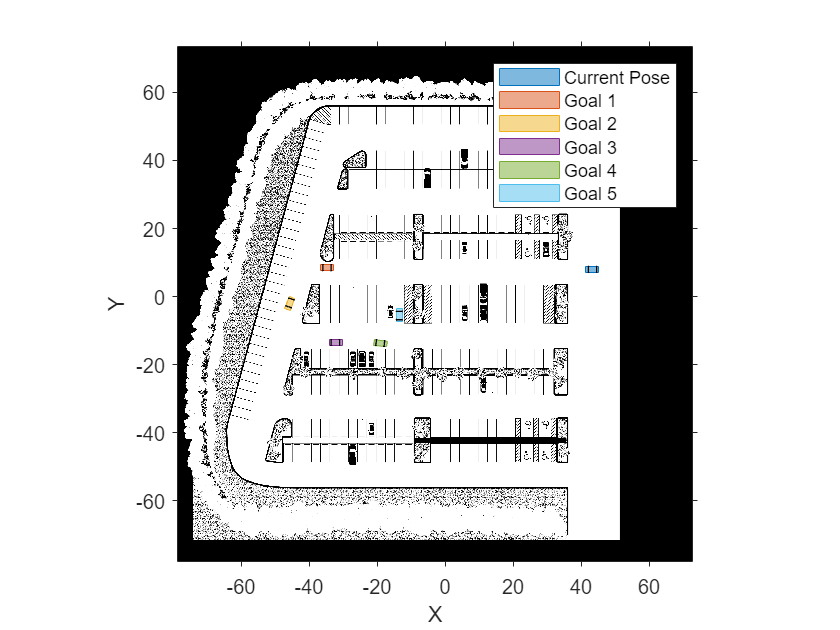


% Plot vehicle at the starting pose
startPose = routePlan.StartPose(1,:);
hold on
helperPlotVehicle(startPose, vehicleDims, 'DisplayName', 'Current Pose')
legend

for n = 1 : height(routePlan)
    % Extract the goal waypoint
    vehiclePose = routePlan{n, 'EndPose'};
    
    % Plot the pose
    legendEntry = sprintf('Goal %i', n);
    helperPlotVehicle(vehiclePose, vehicleDims, 'DisplayName', legendEntry);
    hold on
end
hold off

## **配置 3D 场景和自我车辆**

关闭数字并打开模型。

helperCloseFigures

if ~ispc
    error(['3D Simulation is only supported on Microsoft', char(174), ' Windows', char(174), '.']);
end

modelName = 'APVWith3DSimulation';
open_system(modelName)
snapnow

此模型扩展了 Simulink 示例中的自动泊车代客中使用的模型，添加了两个用于在 3D 场景中可视化车辆的模块：

- **模拟 3D 场景配置**：实现 3D 模拟环境。场景**名称**参数设置为`Large parking lot`。

- **Simulation 3D Vehicle with Ground Following**：提供一个界面，可以改变 3D 场景中车辆的位置和方向。**车辆的Type**设置为`Hatchback`与中的车辆尺寸一致`costmap`。该块的输入是以米为单位的车辆`[X, Y]`位置和`Yaw`以度为单位的航向角。这些值位于世界坐标系中。

## **在 3D 场景中可视化车辆运动**

模拟模型以查看车辆如何驶入所需的停车位。

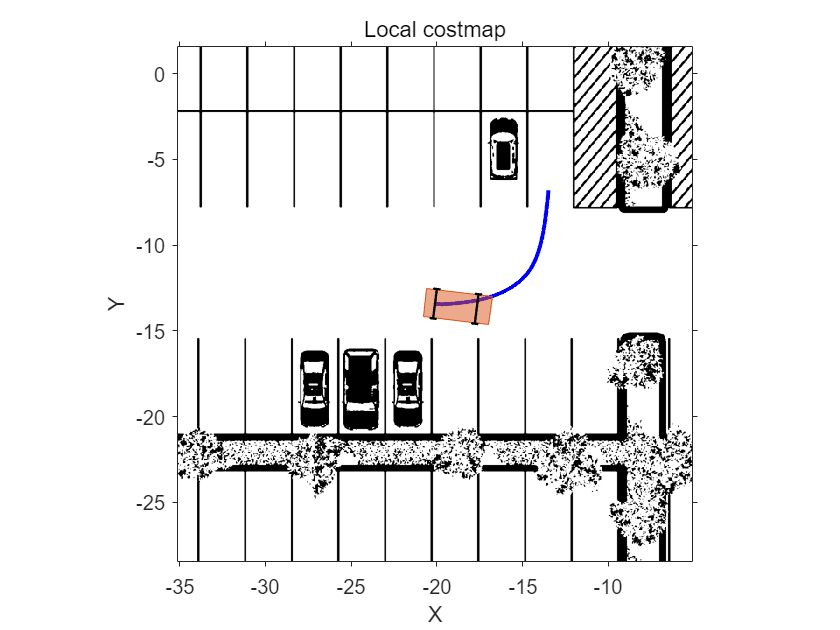

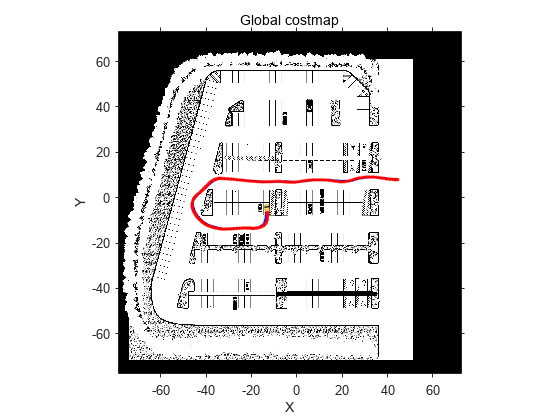

sim(modelName)

[在仿真运行时，Simulink 环境通过Simulation 3D Vehicle with Ground Following](https://ww2.mathworks.cn/help/driving/ref/simulation3dvehiclewithgroundfollowing.html)块更新 3D 可视化引擎中车辆的位置和方向。一个新窗口显示 3D 可视化引擎中的自我车辆。该`Automated Parking Valet`图以蓝色显示规划路径，以红色显示车辆的实际路径。该`Parking Maneuver`图显示了用于搜索最终停车操作的局部成本图。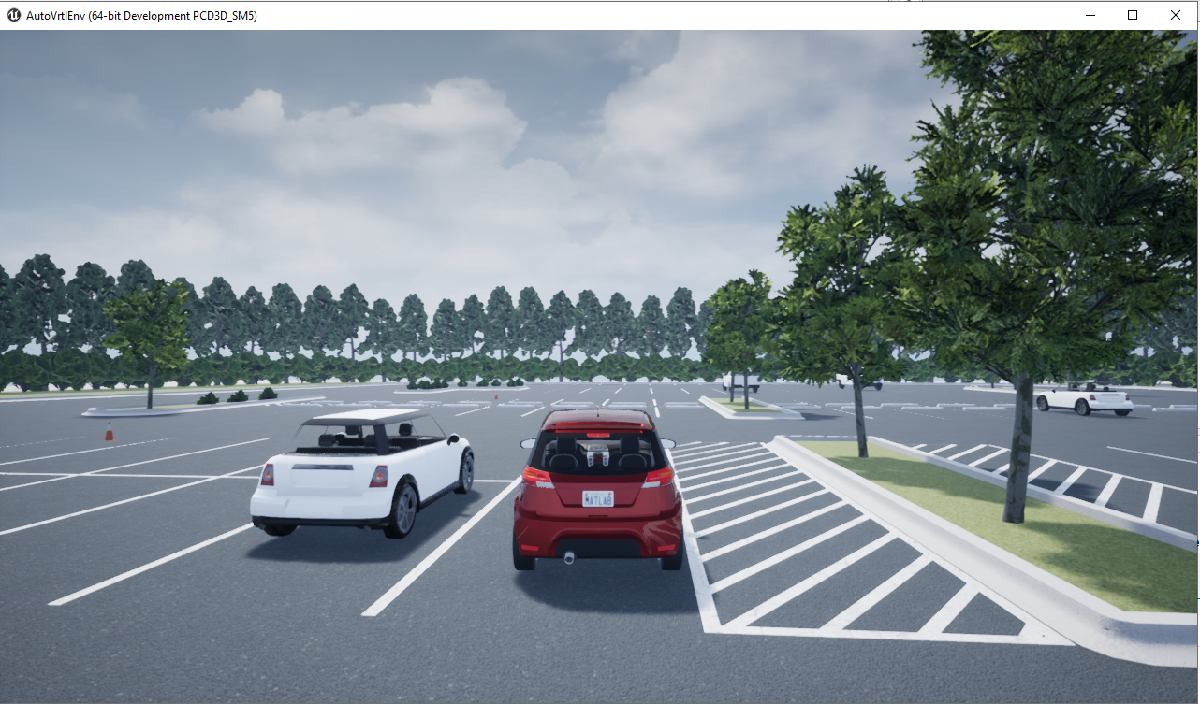

## **探索增强型路径规划系统**

Path Planner 模块使用最佳快速探索随机树 (RRT*) 算法通过环境地图规划一条可行路径。为了保证规划算法的性能，路径规划模块被修改为包括两个独立的模块：

- **Driving Mode**：使用整个停车场的costmap进行导航。此实现也用于[Simulink 示例中的自动代客泊车](https://ww2.mathworks.cn/help/driving/ug/automated-parking-valet-in-simulink.html)。

- **停车模式**：使用本地成本图进行最终停车操作。局部成本图是成本图的子图，形状为正方形。要指定此地图的大小，请使用Path Planner 模块对话框的**Local costmap size (m)参数。**具有较小尺寸的成本图显着降低了搜索通往最终停车位的可行路径的计算负担。它还增加了在给定相同规划器设置的情况下找到可行路径的可能性。

打开路径规划器子系统。

open_system([modelName, '/Path Planner'], 'force')

[这两个路径规划器模块作为启用子系统](https://ww2.mathworks.cn/help/simulink/slref/enabledsubsystem.html)(Simulink)块实现。使能信号来自行为规划器模块发送的`IsParkingManeuver`输入总线中的信号。`Config`启用停车模式子系统后，将创建一个局部成本图，中心作为车辆的当前位置。

关闭模型和图形。

bdclose all
helperCloseFigures

## **结论**

此示例展示了如何在 Simulink 示例中将 3D 仿真与现有的自动泊车代客集成，以可视化 3D 停车场场景中车辆的运动。

## 支持函数

**helperCreateCostmapFromImage**

function BW = helperCreateCostmapFromImage(sceneImage) %#ok<DEFNU>
%helperCreateCostmapFromImage Create a costmap from an RGB image.

% Flip the scene image
sceneImage = flipud(sceneImage);

% Call the autogenerated code from the Color Thresholder app
BW = helperCreateMask(sceneImage);

% Smooth the image
BW = im2uint8(medfilt2(BW));

% Resize
BW = imresize(BW, 0.5);

% Compute complement 
BW = imcomplement(BW);
end

**helperCreateMask**

function [BW,maskedRGBImage] = helperCreateMask(RGB) 
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 22-Oct-2021
%------------------------------------------------------


% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 42.000;
channel1Max = 179.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 66.000;
channel2Max = 191.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 67.000;
channel3Max = 164.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
end

**helperCloseFigures**

function helperCloseFigures()
%helperCloseFigures Close all the figures except the simulation visualization

% Find all the figure objects
figHandles = findobj('Type', 'figure');

% Close the figures
for i = 1: length(figHandles)
    close(figHandles(i));
end
end

*Copyright 2019 The MathWorks, Inc.*